# MNIST con capas densas

En este script vamos a resolver el problema de determinar dígitos escritos a mano con una red neuronal de capas densas.

addpath(genpath('examples'));
SEED = 12345;
rng(SEED);

## Carga del conjunto de datos

dir = 'examples/data/mnist/';

trainFilename = [dir 'mnist_train.gz'];
trainLabelsFilename = [dir 'mnist_train_labels.gz'];
testFilename = [dir 'mnist_test.gz'];
testLabelsFilename = [dir 'mnist_test_labels.gz'];

XTrain = processImagesMNIST(trainFilename);


Read MNIST image data...
Number of images in the dataset:  60000 ...


YTrain = processLabelsMNIST(trainLabelsFilename);


Read MNIST label data...
Number of labels in the dataset:  60000 ...


XTest = processImagesMNIST(testFilename);


Read MNIST image data...
Number of images in the dataset:  10000 ...


YTest = processLabelsMNIST(testLabelsFilename);


Read MNIST label data...
Number of labels in the dataset:  10000 ...



XTrain = extractdata(XTrain);
XTest = extractdata(XTest);

## Subivisión del conjunto de entrenamiento para validación

[trainInd, valInd, ~] = dividerand(length(XTrain), .9, .1, .0);

XVal = XTrain(:, :, :, valInd);
YVal = YTrain(valInd);
XTrain = XTrain(:, :, :, trainInd);
YTrain = YTrain(trainInd);

## Creación de la red

layers = [
    featureInputLayer(28 * 28, 'Name', 'input')
    
    fullyConnectedLayer(512, 'Name', 'dense')
    reluLayer('Name', 'relu')
    
    fullyConnectedLayer(10, 'Name', 'head')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];

## Adecuación de la entrada

Como sólo vamos a usar capas densas necesitamos que la entrada sea un array unidimensional.

XTrainIn = reshape(XTrain, 28 * 28, []).';
XValIn = reshape(XVal, 28 * 28, []).';
XTestIn = reshape(XTest, 28 * 28, []).';

## Opciones de entrenamiento

miniBatchSize = 16;

options = trainingOptions('sgdm', ...
    'MiniBatchSize', miniBatchSize, ...
    'MaxEpochs', 4, ...
    'InitialLearnRate', .01, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XValIn, YVal}, ...
    'ValidationFrequency', miniBatchSize * 8, ...
    'Verbose', false, ...
    'Plots', 'training-progress' ...
);

## Entrenamiento

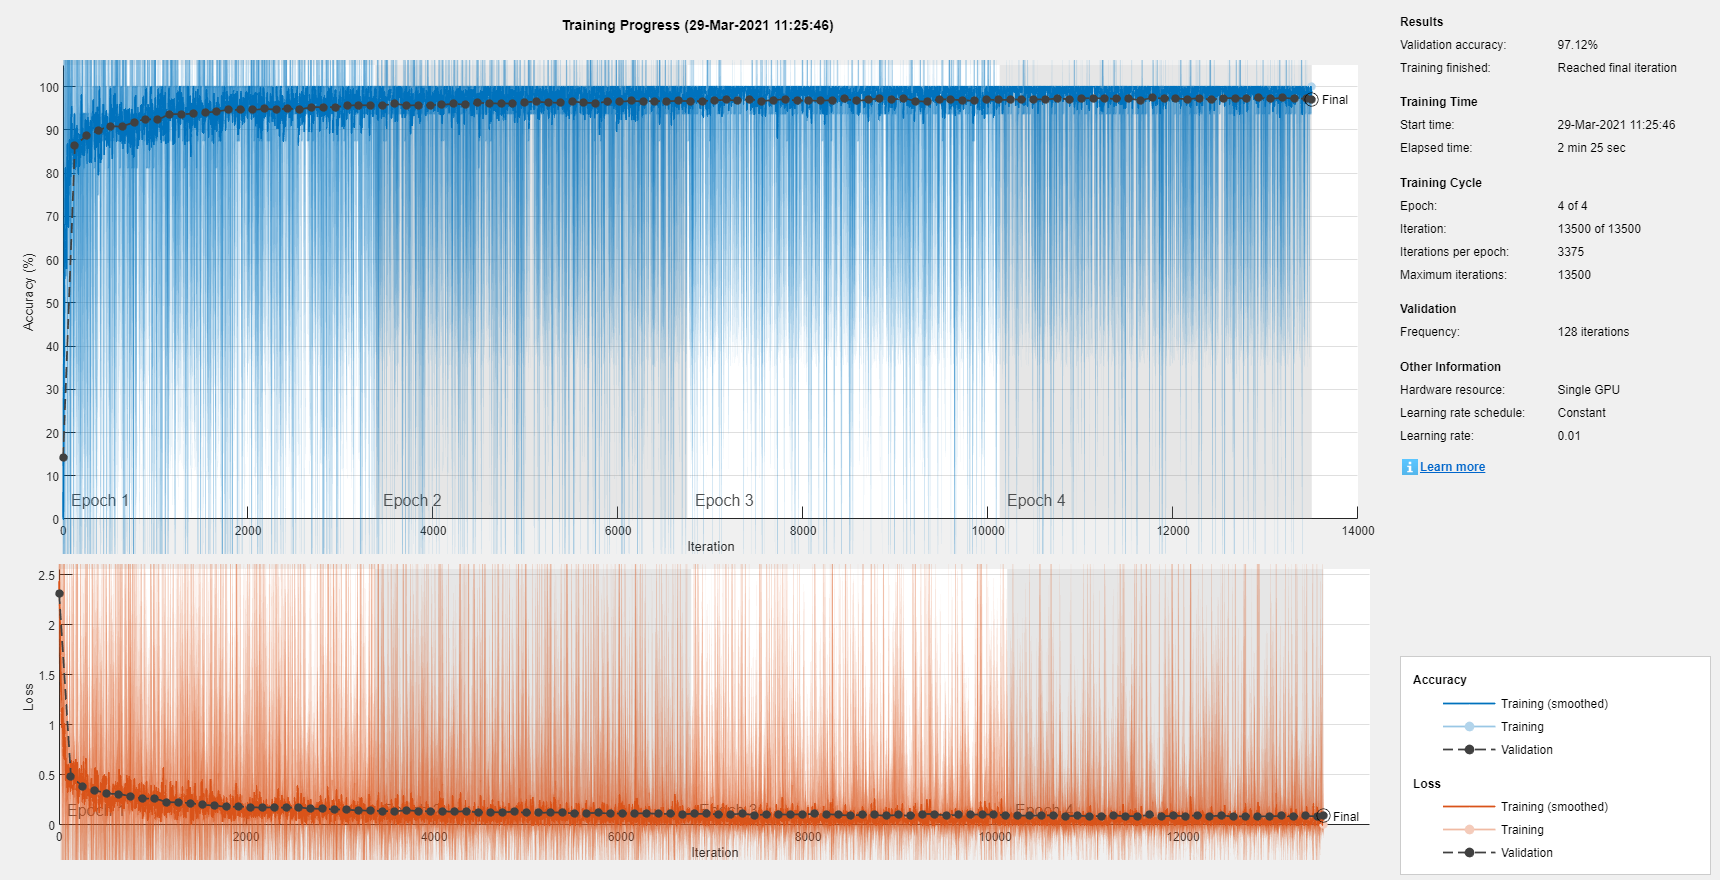

[net, info] = trainNetwork(XTrainIn, YTrain, layers, options);

save('examples/models/mnistFC.mat', 'net');
save('examples/models/mnistFCInfo.mat', 'info');

## Evaluación

categories = net.Layers(end).Classes;

probs = predict(net, XTestIn);
[~, YPred] = max(probs, [], 2);
YPred = categories(YPred);
acc = sum(YPred == YTest) / length(YTest);

fprintf("****************\n");

****************


fprintf("Accuracy: %0.4f\n", acc);

Accuracy: 0.9773


fprintf("****************\n");

****************


## Resultados

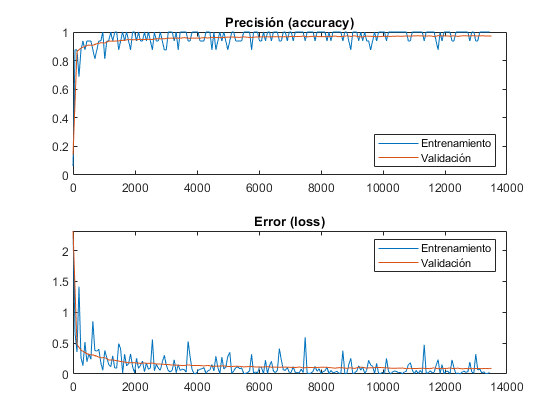

plotTraining(info, miniBatchSize * 4);

## Ejemplos

rng(SEED);
examples = zeros(28, 28, 10);
for i = 1:10
    filtered = XTrain(:, :, YTrain == categories(i));
    index = floor(rand * size(filtered, 3)) + 1;
    examples(:, :, i) = filtered(:, :, index);
end

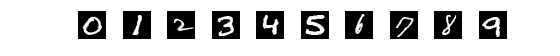

figure
position = get(gcf, 'Position');
set(gcf, 'Position',  [position(1:3) 28*2]);
for i = 1:10
    subplot(1, 10, i);
    imshow(examples(:, :, i));
end

examples = zeros(28, 28, 10);
exProbs = zeros(10, 1);
exPred = zeros(10, 1);
for i = 1:10
    indices = YTest == categories(i);
    filtered = XTest(:, :, indices);
    index = floor(rand * size(filtered, 3)) + 1;
    examples(:, :, i) = filtered(:, :, index);
    
    filtered = YPred(indices);
    exPred(i) = filtered(index);
    
    filtered = probs(indices, :);
    exProbs(i) = filtered(index, exPred(i));
end

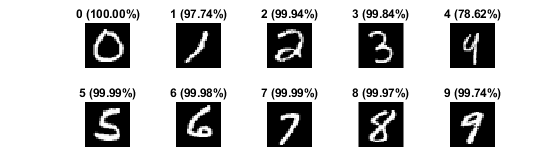

figure
position = get(gcf, 'Position');
set(gcf, 'Position',  [position(1:3) 28*6]);
for i = 1:10
    subplot(2, 5, i);
    imshow(examples(:, :, i));
    title(strcat(string(categories(exPred(i))), ...
        sprintf(' (%0.2f%%)', exProbs(i) * 100)));
end